# Fitting orientation data

Sometimes you may wish to use continuous report data on dimensions that span only 180 degrees. For example, oriented lines that do not have a preferred direction. MemToolbox supports this via the Orientation() wrapper function. In particular, for such data you should specify your .errors as ranging from -90 to 90, rather than -180 to 180, and then wrap your chosen model in Orientation() before calling any of the fitting functions.

Warning:

If you specify data that appears to be orientation data, but the model you include is not wrapped with the Orientation() wrapper function, MemFit will not automatically detect this error

          Model:   Standard mixture model with bias (for orientation)
     Parameters:   mu, g, sd

Just a moment while MTB fits a model to your data...

   Running 3 chains...
   ... not yet converged (200); btw/within variance: 2.05
   ... not yet converged (400); btw/within variance: 1.86
   ... not yet converged (600); btw/within variance: 1.93
   ... not yet converged (800); btw/within variance: 1.14
   ... chains converged after 1000 samples!
   ... collecting 4500 samples from converged distribution

...finished. Now let's view the results:

parameter	MAP estimate	lower CI	upper CI
---------	------------	--------	--------
      mu	      15.818	   3.375	  27.529
       g	       0.006	   0.002	   0.442
      sd	      23.596	  16.886	  41.457



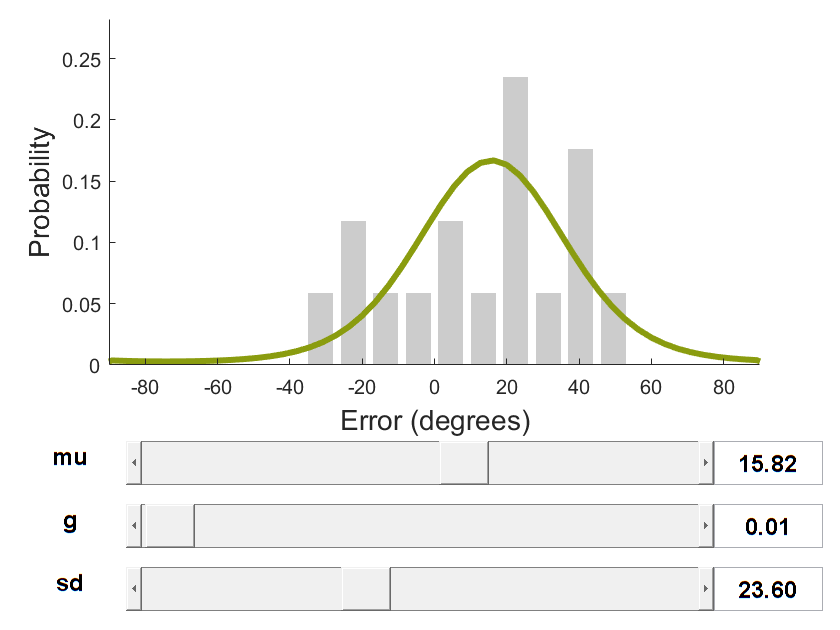

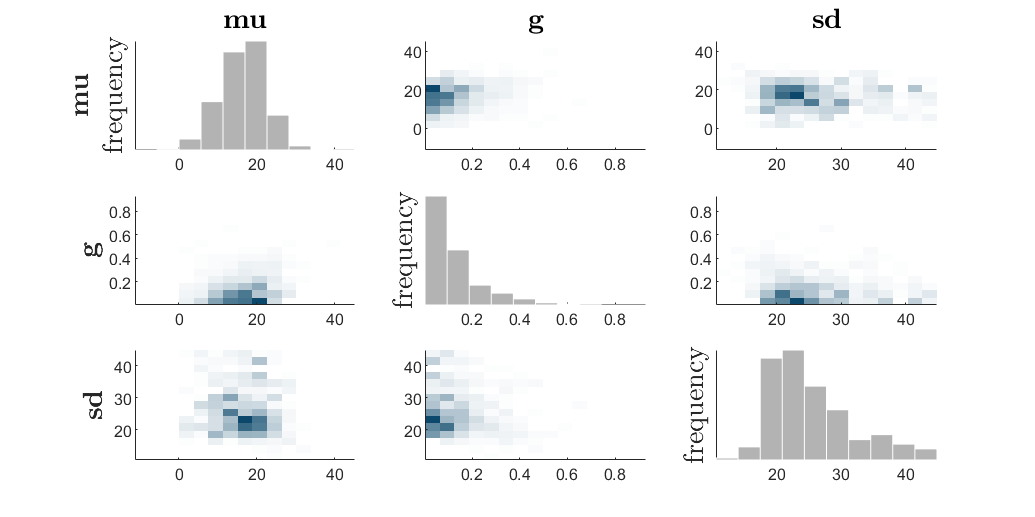

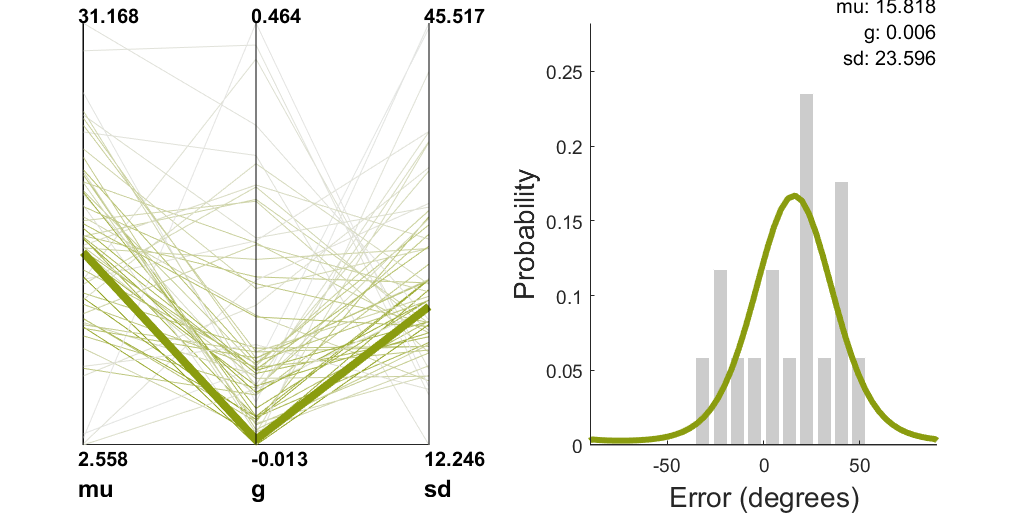

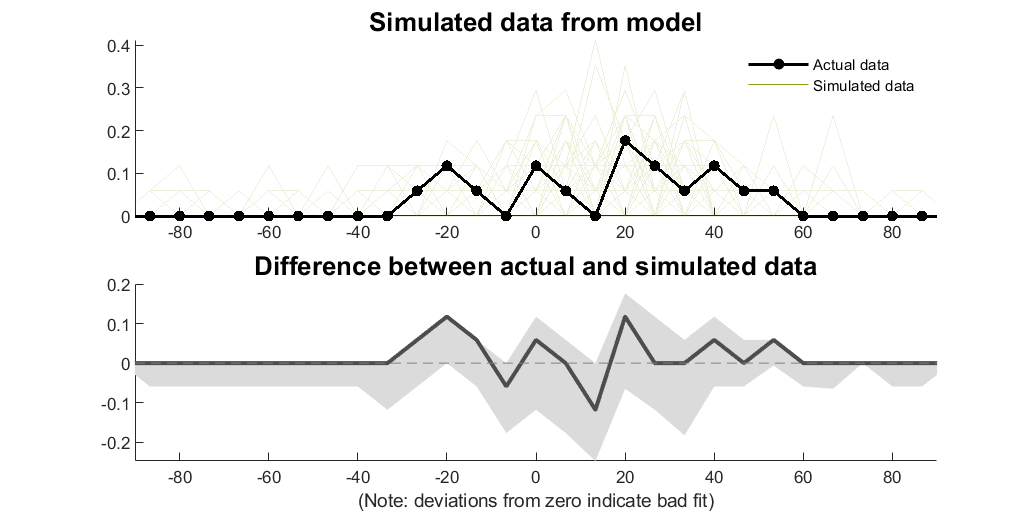


This analysis was performed using MemToolbox version 1.0.0.



ans = struct with fields:
       posteriorMean: [16.4018 0.1212 25.5545]
     posteriorMedian: [16.8187 0.0883 23.9346]
        maxPosterior: [15.8183 0.0063 23.5958]
       lowerCredible: [3.3752 0.0015 16.8865]
       upperCredible: [27.5285 0.4416 41.4573]
    posteriorSamples: [1×1 struct]


clear all;
data.errors = [-12 3 38 27 -29 21 -22 52 -2 -19 21 17 38 6 34 25 44];
% This will fit a model that wraps from -90 to 90 degrees, and will adjust the first and third 
% parameters of the model to account for this wrapping. These parameters have values in 
% degrees, and so must be adjusted to account for the different wrapping . The model will 
% have “(for orientation)” added to the end of its name
MemFit(data, Orientation(WithBias(StandardMixtureModel), [1,3]))